d = linspace(1,10);         %diamiter in m
r = d./2;
a = 4*pi().*(r.^2);         %surface area

p = 0.5;    %payload mass in kg
wpa = 0.0075;                %kg/m^2 mass per area
w_b = (a.*(wpa))+p;         % mass of balloon and payload

V = (4/3)*pi()*(r.^3);         % volume of balloon
roh_c = 1.204; % inital density of air
Tc = 20;  %outside temp
Tb = 25; %temp in balloon
beta = 0.0034; %1/c 

roh_b = roh_c./(1+beta.*(Tb-Tc)); % density in balloon

g_c = 9.81;
Fl = V.*(roh_c-roh_b).*(g_c); %lift force
Fg = (w_b*(g_c));
F = Fl-Fg; %total force

for i =1:length(d)
    if Fl(i)<Fg(i)
    else
        min_diamiter = d(i);
        sprintf('Min diamiter: %0.5f m',d(i))
        break
    end      
end

ans = 'Min diamiter: 4.54545 m'

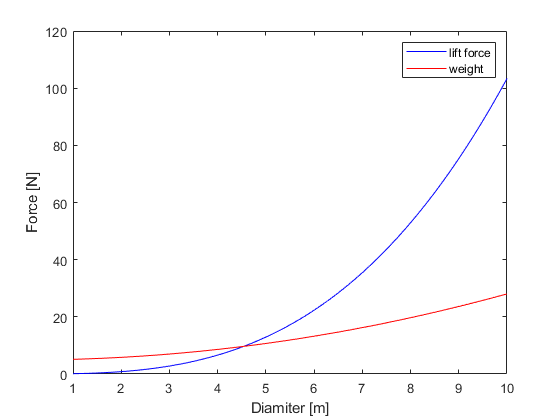


clf
figure (2)
plot(d,Fl,'b')
hold on
plot(d,Fg,'r')
ylabel('Force [N]')
xlabel('Diamiter [m]')
legend('lift force','weight')